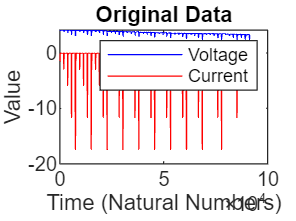

% Clear workspace and variables
clear all; close all; clc;

% Define current value (adjust as per your data)
curr = 18;

% Load data from .mat file
data_path = '10deg.mat';
mydata = load(data_path);

% Extract fields from loaded data
y = mydata.meas.Voltage;   % Battery output voltage
z = mydata.meas.Current;   % Battery output current

% Generate a new time vector as natural numbers
x = (1:length(y))'; % Natural numbers from 1 to the length of y

% % Plot the original data
figure;
plot(x, y, 'b', 'DisplayName', 'Voltage');
hold on;
plot(x, z, 'r', 'DisplayName', 'Current');
xlabel('Time (Natural Numbers)'); ylabel('Value');
title('Original Data');
legend show;

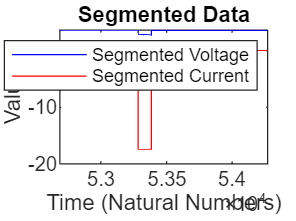


% % Define time points for segmentation
x1 = 52687; % Example starting point (adjust as needed)
x2 = 54270; % Example ending point (adjust as needed)

limit1 = find(x == x1, 1);
limit2 = find(x == x2, 1);
% % Find indices for segmentation
% limit1 = find(x >= x1, 1);
% limit2 = find(x <= x2, 1, 'last');
 
% % Segment the data
% if isempty(limit1) || isempty(limit2)
%     error('Segmentation limits not found in the data. Check x1 and x2 values.');
% end
 
x_dash = x(limit1:limit2);
y_dash = y(limit1:limit2);
z_dash = z(limit1:limit2);

% Plot segmented data
figure;
plot(x_dash, y_dash, 'b', 'DisplayName', 'Segmented Voltage');
hold on;
plot(x_dash, z_dash, 'r', 'DisplayName', 'Segmented Current');
xlabel('Time (Natural Numbers)'); ylabel('Value');
title('Segmented Data');
legend show;


%% Fit: 'rc_fit_part1'.
[xData, yData] = prepareCurveData(x_dash, y_dash);

% Set up fittype and options for 2-RC model
ft = fittype('a - b1*(1-exp(-x/c1)) - b2*(1-exp(-x/c2))', ...
    'independent', 'x', 'dependent', 'y');
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.Display = 'off';
opts.StartPoint = [1 0.5 1 0.5 1]; % Adjust the starting points as needed

% Fit model to data
[fitresult, gof] = fit(xData, yData, ft, opts);

fitresult

fitresult =      General model:
     fitresult(x) = a - b1*(1-exp(-x/c1)) - b2*(1-exp(-x/c2))
     Coefficients (with 95% confidence bounds):
       a =       2.351
       b1 =     -0.8511
       b2 =     -0.3511
       c1 =         0.5
       c2 =           1


fit_1 = fitresult;
fit_1

fit_1 =      General model:
     fit_1(x) = a - b1*(1-exp(-x/c1)) - b2*(1-exp(-x/c2))
     Coefficients (with 95% confidence bounds):
       a =       2.351
       b1 =     -0.8511
       b2 =     -0.3511
       c1 =         0.5
       c2 =           1


%% ------------------------parameter estimation for part1----------------------------
a = fit_1.a;
b1 = fit_1.b1;
c1 = fit_1.c1;
b2 = fit_1.b2;
c2 = fit_1.c2;
% g1 = fit_2.g1;
% h1 = fit_2.h1;
% g2 = fit_2.g2;
% h2 = fit_2.h2;

% Calculate Ro------
R_O = abs(a / curr);

% Calculate R_1-----
R_1 = abs(b1 / curr);

% Calculate C_1-----
C_1 = c1 / R_1;

% Calculate R_2-----
R_2 = abs(b2 / curr);

% Calculate C_2-----
C_2 = c2 / R_2;

% Display results
fprintf('first method');

first method

fprintf('R_O: %f\n', R_O);

R_O: 0.130616


fprintf('R_1: %f\n', R_1);

R_1: 0.047283


fprintf('C_1: %f\n', C_1);

C_1: 10.574645


fprintf('R_2: %f\n', R_2);

R_2: 0.019505


fprintf('C_2: %f\n', C_2);

C_2: 51.268558



%% --------------------parameter estimation--------------------------------

% % Prepare data for curve fitting
% [xData, yData] = prepareCurveData(x_dash, y_dash);
% 
% % Define 2-RC model fit type
% ft = fittype('a - b1*(1-exp(-x/c1)) - b2*(1-exp(-x/c2))', ...
%     'independent', 'x', 'dependent', 'y');
% 
% % Set fit options
% opts = fitoptions('Method', 'NonlinearLeastSquares');
% opts.Display = 'off';
% opts.StartPoint = [1 0.5 1 0.5 1]; % Adjust starting points based on your data
% 
% % Fit the model to data
% try
%     [fitresult, gof] = fit(xData, yData, ft, opts);
% catch ME
%     error('Curve fitting failed: %s', ME.message);
% end
% 
% % Display the fitting results
% disp('Fitting Results:');
% disp(fitresult);
% 
% % Extract parameters from fit
% a = fitresult.a;
% b1 = fitresult.b1;
% c1 = fitresult.c1;
% b2 = fitresult.b2;
% c2 = fitresult.c2;
% 
% % Calculate resistances and capacitances
% R_O = abs(a / curr); % Ohmic resistance
% R_1 = abs(b1 / curr); % RC branch 1 resistance
% C_1 = c1 / R_1;       % RC branch 1 capacitance
% R_2 = abs(b2 / curr); % RC branch 2 resistance
% C_2 = c2 / R_2;       % RC branch 2 capacitance
% 
% % Display calculated parameters
% fprintf('Calculated Parameters:\n');
% fprintf('R_O: %f Ohms\n', R_O);
% fprintf('R_1: %f Ohms\n', R_1);
% fprintf('C_1: %f Farads\n', C_1);
% fprintf('R_2: %f Ohms\n', R_2);
% fprintf('C_2: %f Farads\n', C_2);
% 
% % Reconstruct and visualize the fitted curve
% y_fit = feval(fitresult, xData);
% figure;
% plot(x_dash, y_dash, 'b', 'DisplayName', 'Actual Voltage');
% hold on;
% plot(x_dash, y_fit, 'r--', 'DisplayName', 'Fitted Voltage');
% xlabel('Time (Natural Numbers)'); ylabel('Voltage');
% title('Fitted vs Actual Data');
% legend show;
